# Violin Fine-Tuner Pitch Analysis Automation Script

% Stepper Motor Parameters
theta_min = 0;
theta_max = 1440;
stepSize = 90;
steps_per_revolution = 200;
positionTheta = (theta_min:stepSize:theta_max)';
positionStep  = positionTheta * (steps_per_revolution/360)';

% Recording Parameters
deviceNum = 1;
sampleRate = 48000; % Hz
bitsPerSample = 16;
numAudioChannels = 1; 
recordTime = 1; % record time in seconds

% Tension Coefficient
tenCoeff = 1;

## Arduino Setup

% This snippet is to fix the "port in use" issue that comes up occasionally
if ~isempty(instrfind)
     fclose(instrfind);
      delete(instrfind);
end
%~~~~~~~~~~~~~~~~~~~~~~~~

ArduinoCOMPort = 'COM6';
Arduino = serial(ArduinoCOMPort, 'baudrate', 38400);
fopen(Arduino);
pause(3)
flushinput(Arduino)
fprintf(Arduino, 'CAL?');
res = fgetl(Arduino)

res =     '69.59
     '


%fclose(Arduino);

## Audio Input Setup

info = audiodevinfo;
inputDevices = struct2table(info.input)

inputDevices = 3×3 table
                                      Name                                          DriverVersion        ID
    ________________________________________________________________________    _____________________    __

    'Primary Sound Capture Driver (Windows DirectSound)'                        'Windows DirectSound'    0 
    'ZOOM Recording Mixer (ZOOM H and F Series Audio) (Windows DirectSound)'    'Windows DirectSound'    1 
    'Microphone (Realtek High Definition Audio) (Windows DirectSound)'          'Windows DirectSound'    2 


recorder = audiorecorder(sampleRate,bitsPerSample,numAudioChannels,deviceNum);

## Audio Test

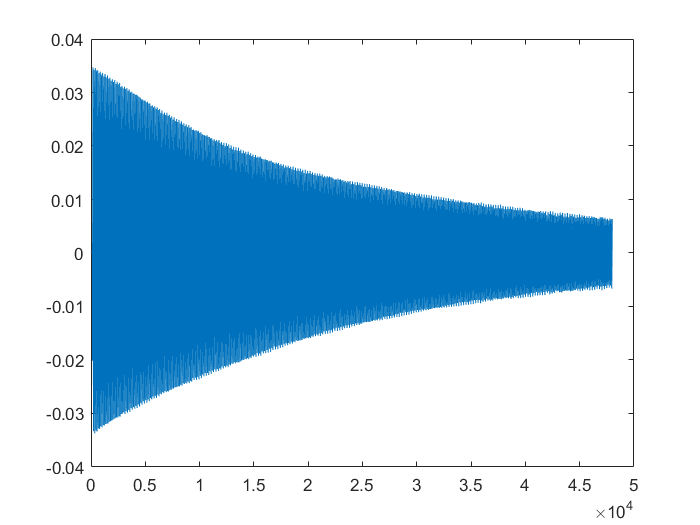

% 'NCF' –– Normalized Correlation Function [1]
% 
% 'PEF' –– Pitch Estimation Filter [2]. The function does not use the amplitude compression described by the paper.
% 
% 'CEP' –– Cepstrum Pitch Determination [3]
% 
% 'LHS' –– Log-Harmonic Summation [4]
% 
% 'SRH' –– Summation of Residual Harmonics [5]

recordblocking(recorder, recordTime);
play(recorder);
y = getaudiodata(recorder);
algorithms = {'NCF','PEF','CEP','LHS','SRH'};

% [f0,loc] = pitch(y,sampleRate, ...
%     'Method','PEF', ...
%     'Range',[50 800], ...
%     'WindowLength',round(sampleRate*0.08), ...
%     'OverlapLength',round(sampleRate*0.05));
% t = loc/sampleRate;

%F = figure(1);
%p1 = subplot(6,1,1);
figure;
plot(y);

ans = 428.9575

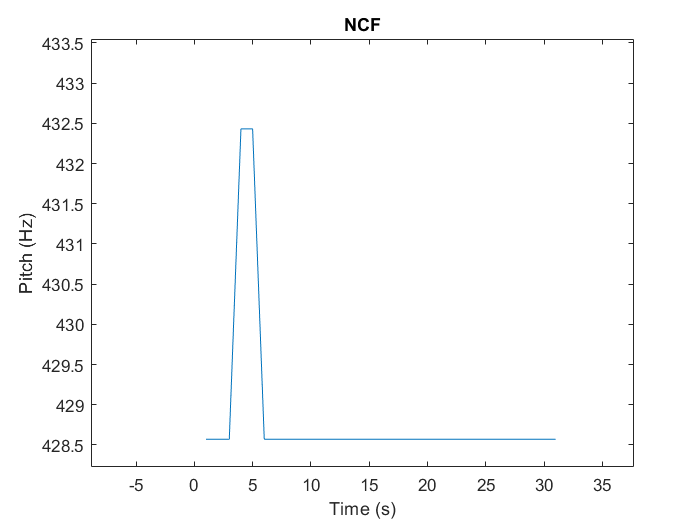

ans = 430.1322

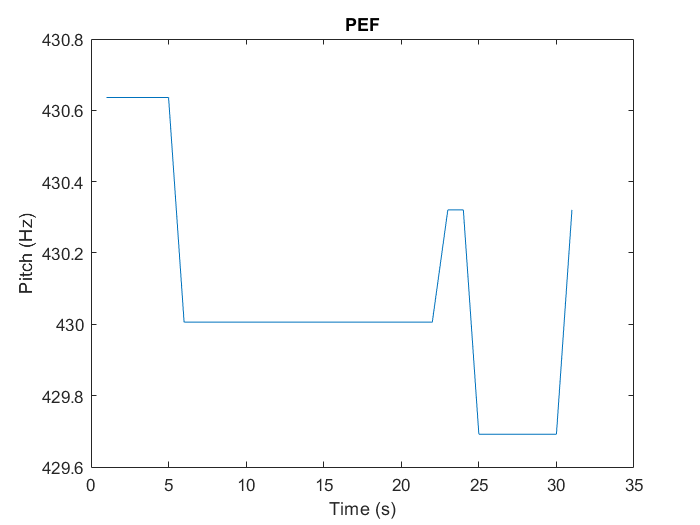


ans =

  0×1 empty double column vector



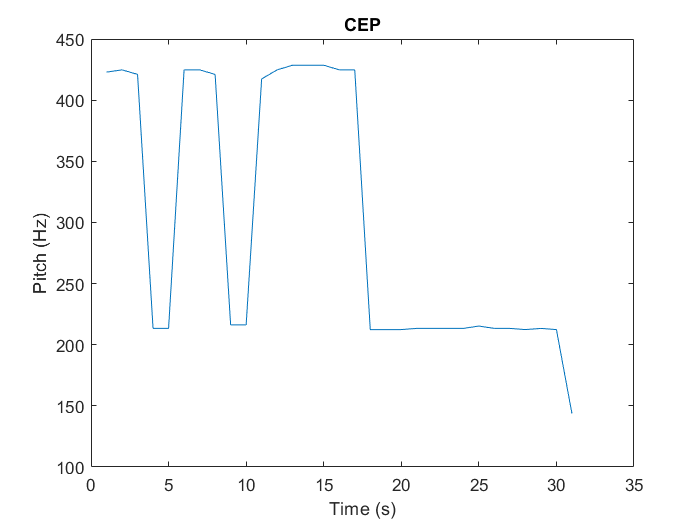

ans = 431.0500

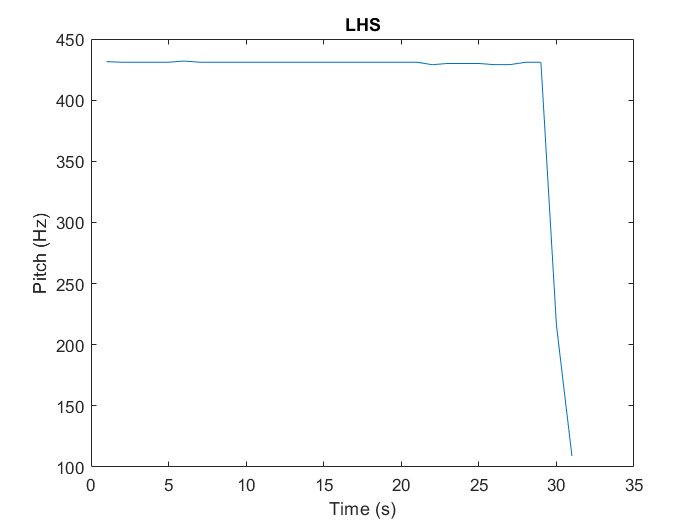

ans = 430

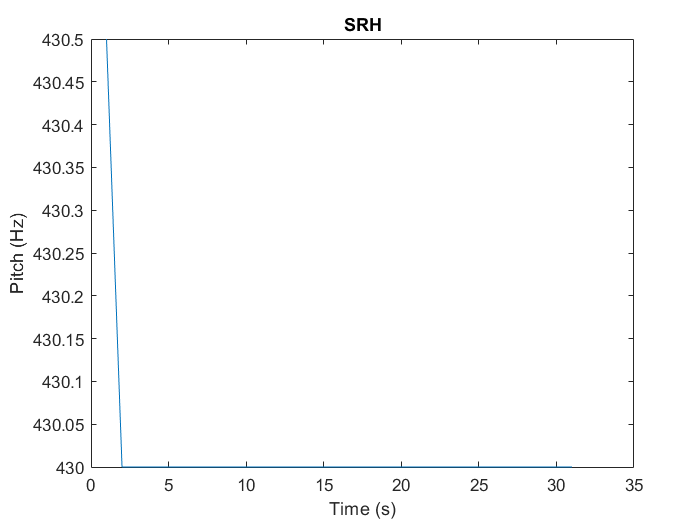


for i = 1:numel(algorithms)
    [f0,loc] = pitch(y,sampleRate, ...
        'Range',[50 800], ...
        'Method',algorithms{i}, ...
        'WindowLength',round(sampleRate*0.08), ...
        'OverlapLength',round(sampleRate*0.05), ...
        'MedianFilterLength',3);
    t = loc/sampleRate;
    
    findSteadyState(f0, 20, 10, 1, 5, 10)
    %subplot(6,1,i+1);
    figure;
    %plot(t,f0);
    plot(f0);
    %axis([0 100 196 660])
    title(algorithms{i})
    ylabel('Pitch (Hz)')
    xlabel('Time (s)')
end

## Automation Script

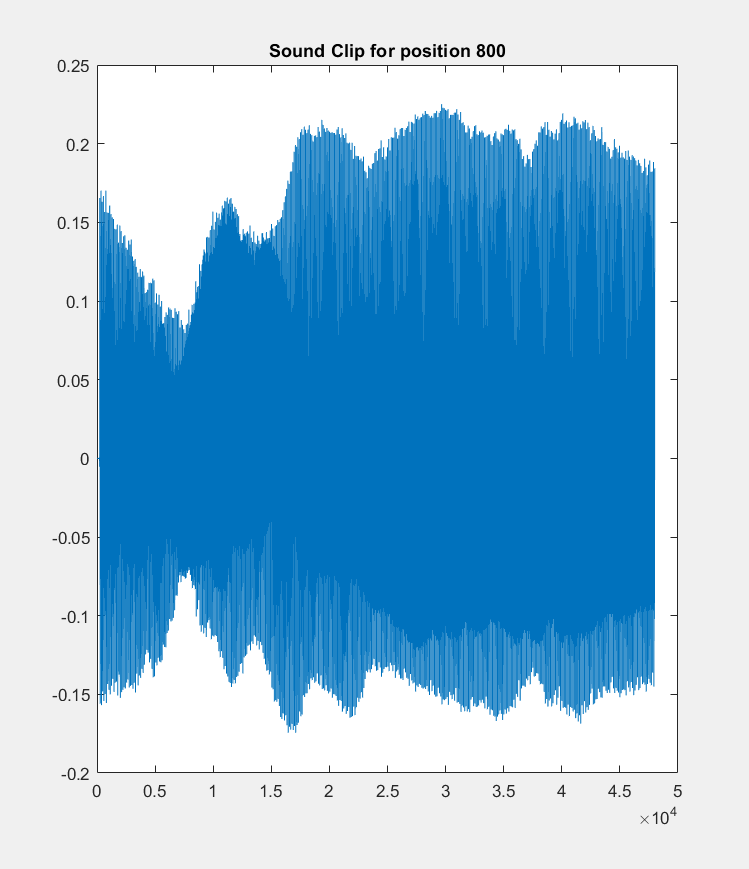

Iteration 1


Iteration 2


Iteration 3


Iteration 4


Iteration 5


Iteration 6


Iteration 7


Iteration 8


Iteration 9


Iteration 10


Iteration 11


Iteration 12


Iteration 13


Iteration 14


Iteration 15


Iteration 16


Iteration 17


figure;
plotbrowser('on') % Open plot browser window

iterations = 1:length(positionStep);
iterations = iterations';
tension = zeros(length(positionStep),1);
samples = cell(length(positionStep),1);
pitchData = cell(length(positionStep),1);
fundamentalFrequency = zeros(length(positionStep),1);

fprintf(Arduino, 'TARE');

for i=1:length(positionStep)
    fprintf("Iteration %d\n",i)
    input(sprintf('Click to move to position %d', positionStep(i)));
    
    % Move Stepper Motor
    fprintf(Arduino, sprintf('POS:%d',positionStep(i)));
    fgetl(Arduino);
    
    input(sprintf('Click to read tension'));
    
    % Read Tension from Arduino
    flushinput(Arduino)
    fprintf(Arduino, 'TENS?');
    tension(i) = str2double(fgetl(Arduino))*tenCoeff;
    
    
    while 1
        input(sprintf('Begin playing and click to record'))
        
        recordblocking(recorder, recordTime);
        %play(recorder);
        y = getaudiodata(recorder);
        plot(y);
        title(sprintf('Sound Clip for position %d',positionStep(i)))
        
        a = input('Recording OK? (y to continue) ','s');
        if a == 'y'
            samples{i} = y;
            break
        end
    end
end


fprintf("Experiment Complete. Closing...");

Experiment Complete. Closing...


% clean up
fclose(Arduino);

fprintf("Done.");

Done.

## Pitch Analysis

Running analysis on sample 1...

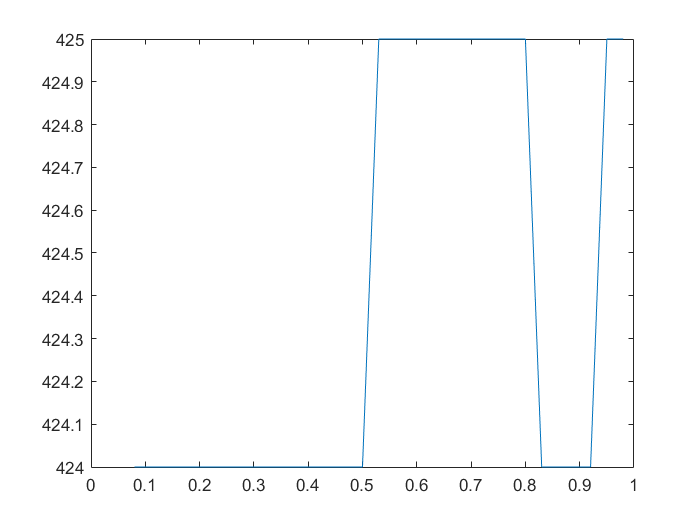

ff = 424.3000

Running analysis on sample 2...

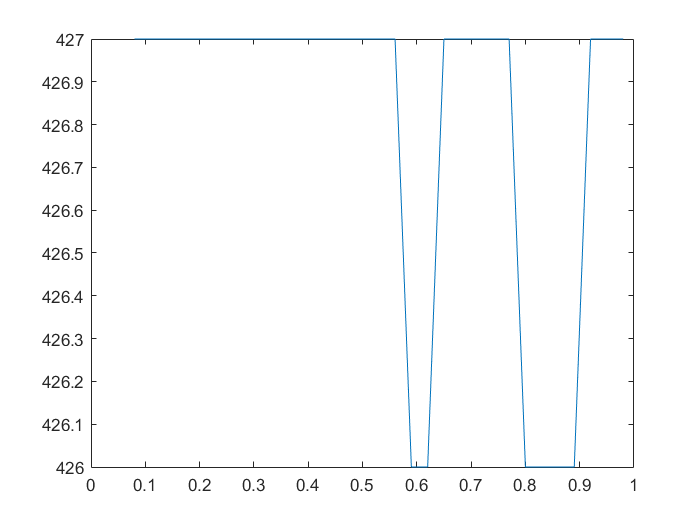

ff = 426.9000

Running analysis on sample 3...

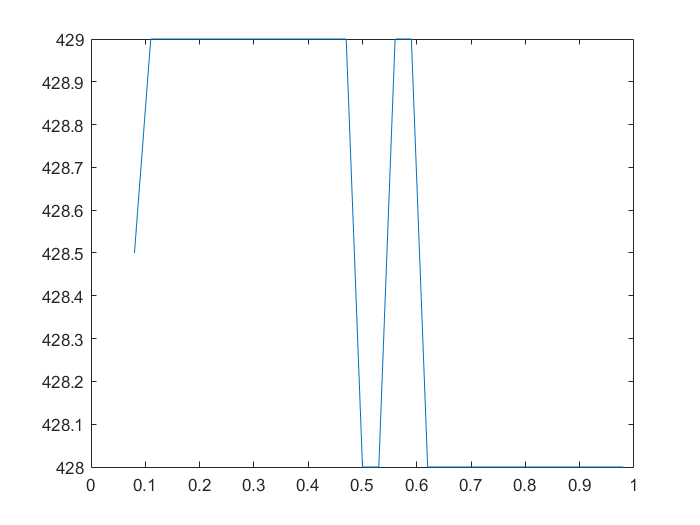

ff = 428.7500

Running analysis on sample 4...

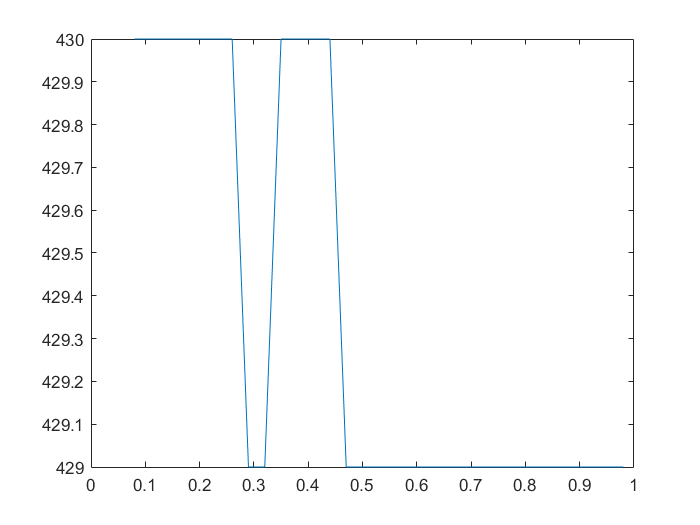

ff = 429.5000

Running analysis on sample 5...

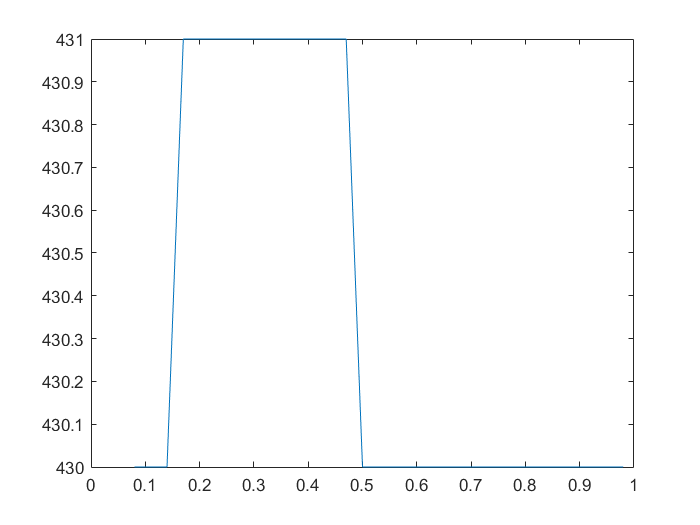

ff = 430.5500

Running analysis on sample 6...

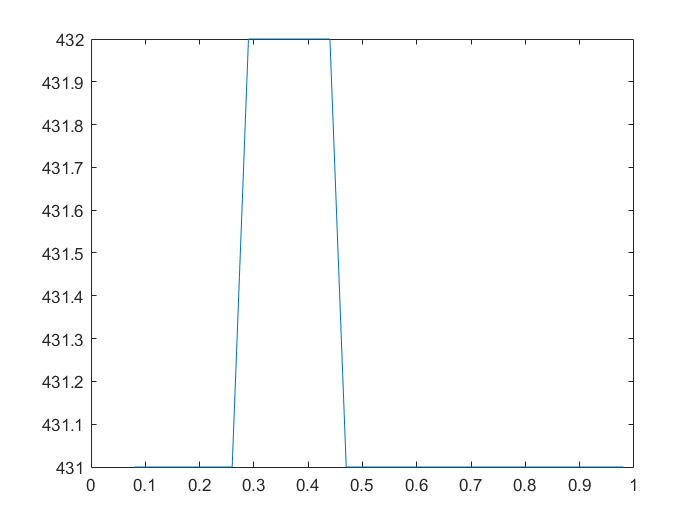

ff = 431.3000

Running analysis on sample 7...

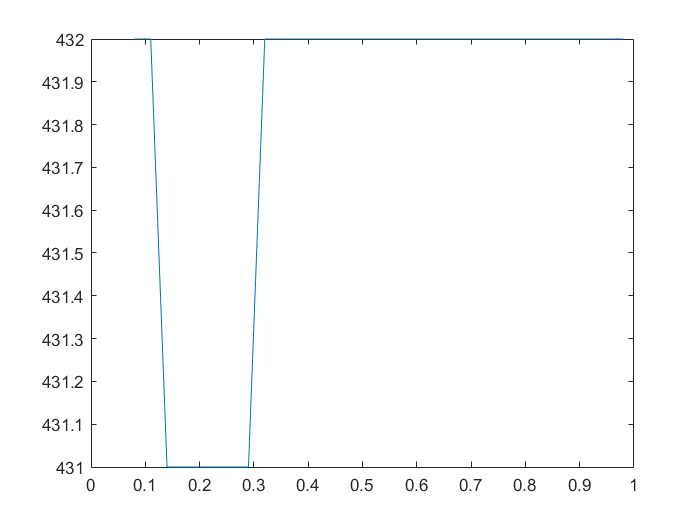

ff = 431.7000

Running analysis on sample 8...

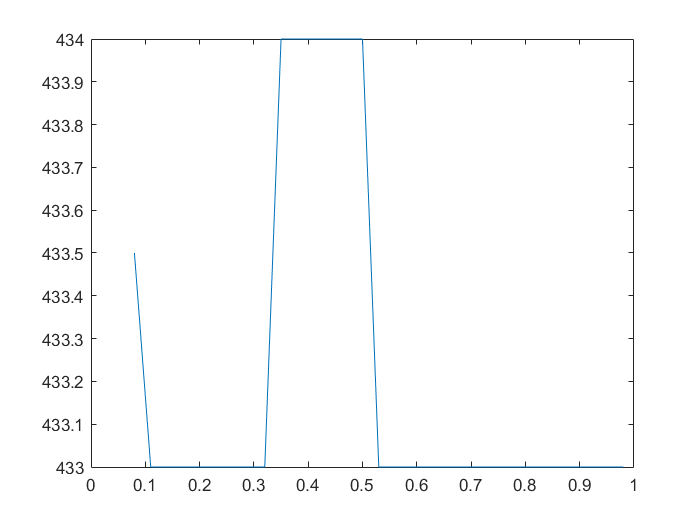

ff = 433.3000

Running analysis on sample 9...

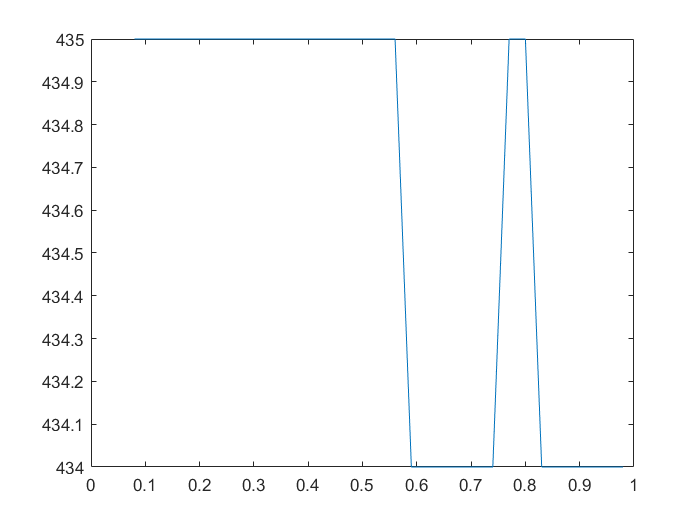

ff = 434.8000

Running analysis on sample 10...

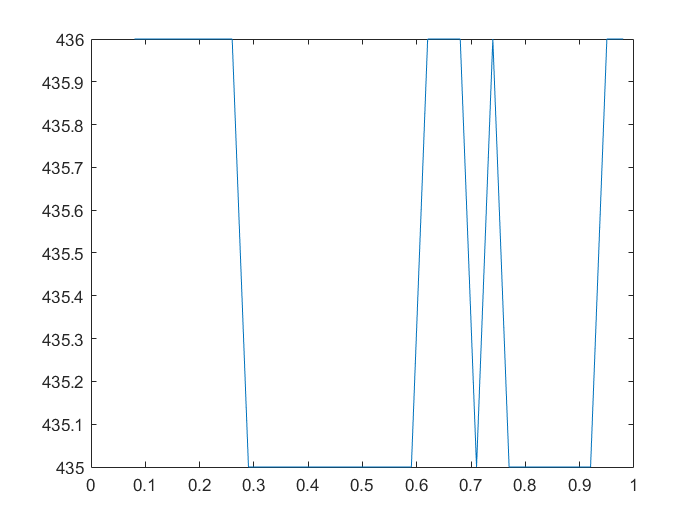

ff = 435.4500

Running analysis on sample 11...

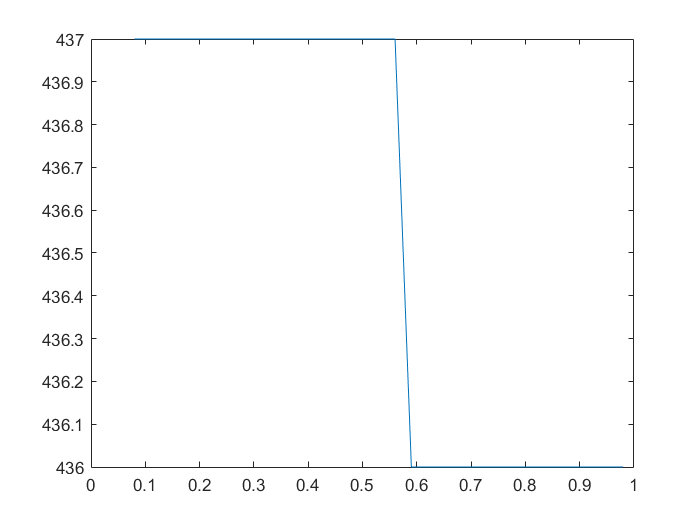

ff = 436.8000

Running analysis on sample 12...

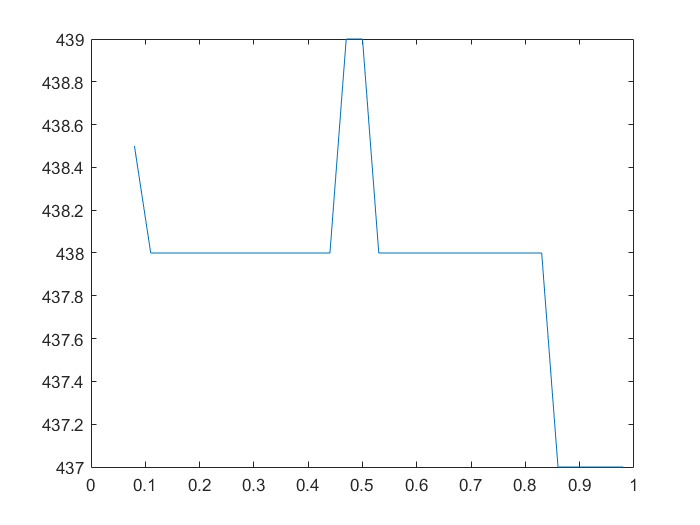

ff = 438.1000

Running analysis on sample 13...

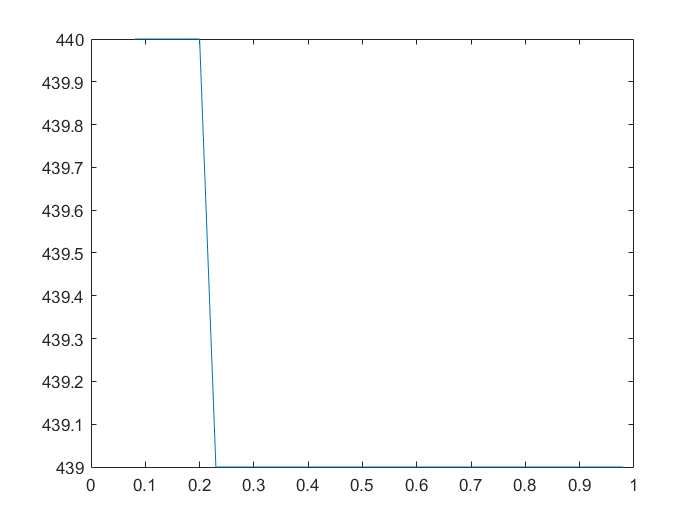

ff = 439.2000

Running analysis on sample 14...

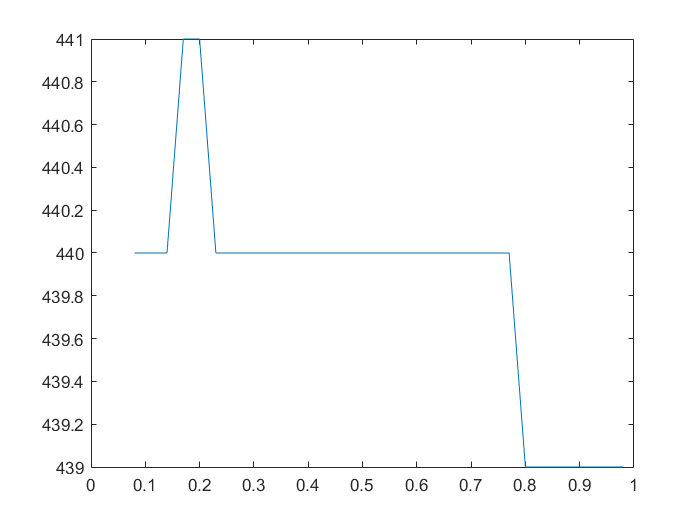

ff = 440.1000

Running analysis on sample 15...

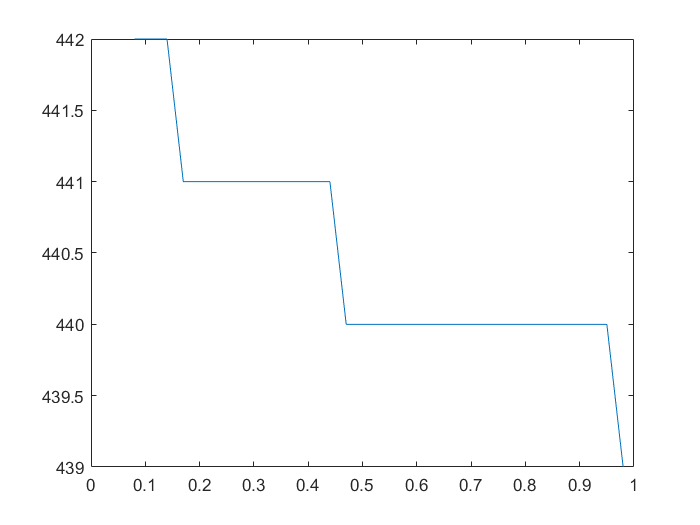

ff = 440.7000

Running analysis on sample 16...

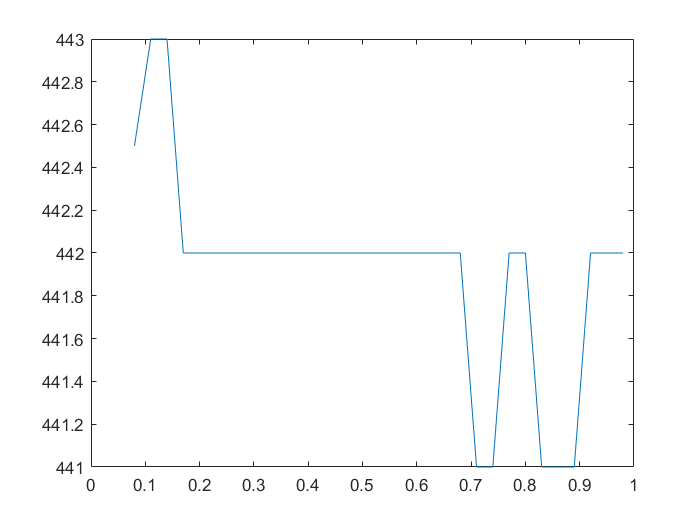

ff = 442.1000

Running analysis on sample 17...

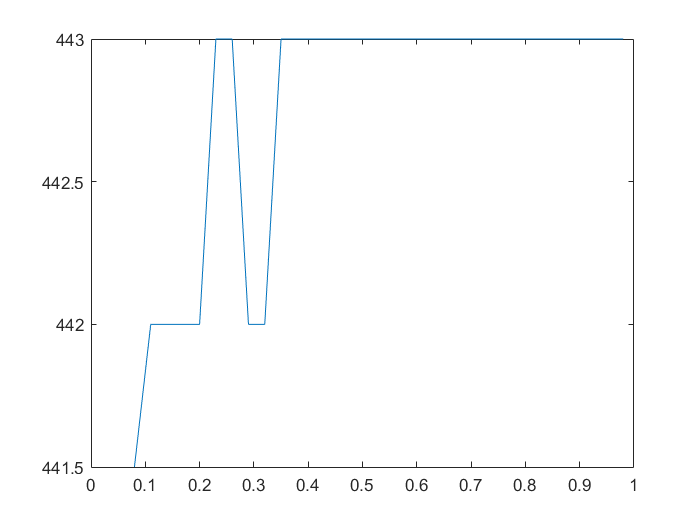

ff = 442.7000

for i = 1:length(samples)
    s = samples{i};
    fprintf("Running analysis on sample %d...",i);
    [f0,loc] = pitch(s,sampleRate, ...
        'Method','LHS', ...
        'Range',[196 660], ...
        'MedianFilterLength',3, ...
        'WindowLength',round(sampleRate*0.08), ...
        'OverlapLength',round(sampleRate*0.05));
    t = loc/sampleRate;
    figure;
    plot(t,f0);
    pitchData{i} = [t,f0];
    ff = findSteadyState(f0, 20, 10, 1, 5, 10)
    fundamentalFrequency(i) = ff;
end

fprintf("Analysis Complete!");

Analysis Complete!

## Generate Tables

data = table(iterations,positionStep,positionTheta,tension,samples,pitchData,fundamentalFrequency)

data = 17×7 table
    iterations    positionStep    positionTheta    tension        samples           pitchData      fundamentalFrequency
    __________    ____________    _____________    _______    ________________    _____________    ____________________

         1              0                0         1.2788     [48000×1 double]    [31×2 double]            424.3       
         2             50               90         31.943     [48000×1 double]    [31×2 double]            426.9       
         3            100              180         56.614     [48000×1 double]    [31×2 double]           428.75       
         4            150              270         82.996     [48000×1 double]    [31×2 double]            429.5       
         5            2

save('experiment_data.mat', 'data');

## Generate Figures

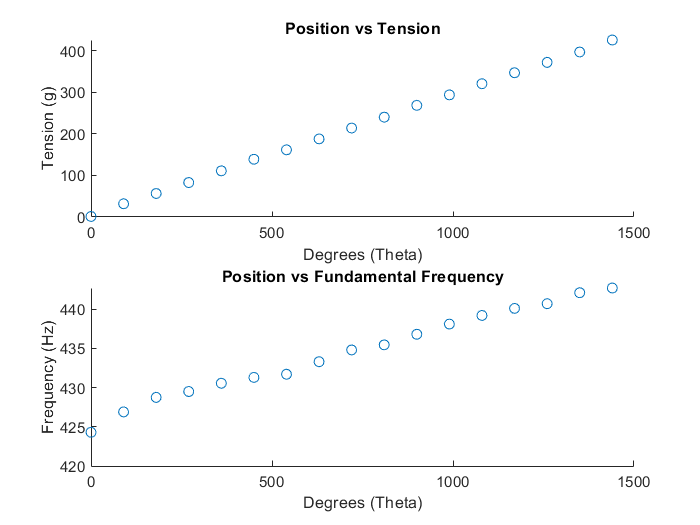

figure(1)
subplot(2,1,1)
scatter(positionTheta,tension)
title("Position vs Tension")
xlabel("Degrees (θ)")
ylabel("Tension (Δg)")
subplot(2,1,2)
scatter(positionTheta,fundamentalFrequency)
title("Position vs Fundamental Frequency")
xlabel("Degrees (θ)")
ylabel("Fundamental Frequency (Hz)")